# Large shock SV

- Implementing the Lenza - Primiceri modell in BEAR6


clear
close all
rehash path

addpath ../sandbox
addpath ../bear


## Convenience functions

The `extremesFunc` function compresses any number of samples (draws from the posterior) into two numbers - the minimum and the maximum.


percentiles = [10, 50, 90];
prctilesFunc = @(x) prctile(x, percentiles, 2);
extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

defaultColors = get(0, "defaultAxesColorOrder");


## Prepare data and a reduced-form model

inputTbx = tablex.fromCsv("covid.csv");

estimStart = datex.m(1990,1);
estimEnd = datex.m(2021,5);
estimSpan = datex.span(estimStart, estimEnd);

meta = model.Meta( ...
    endogenous=["UNEMP","EMP","PCE","PCE_SERV","PCE_price","PCE_SERV_price","PCE_CORE_price"], ...
    units="", ...
    exogenous=[], ...
    order=13, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=12 ...
    ...
);
keyboard
dataH = model.DataHolder(meta, inputTbx);

estimatorR = estimator.LargeShockSV(meta, ...
    AutoRegression = 1, ...
    Lambda1 = 0.120645548495565, Lambda3 = 2, ... %Minnesota hyperparams on B
    Mult0 = [20, 10, 5], ScaleMult = [1, 1, 1], ShapeMult = [1, 1, 1], ... %independent scaling factor hyper params
    MultAR0 = 0.2, AlphaMultAR = 3.035685473974237, BetaMultAR = 1.508921347750411, ... % scaling factor AR param hyper params
    Turningpoint = datex.m(2020,3)); %Date for the first multiplier

modelR = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR ...
    , stabilityThreshold=Inf ...
);

modelR.Estimator.Settings

ans =   LargeShockSV with properties:

                    Solver: @defaultSolver
                     Mult0: [20 10 5]
                 ScaleMult: [1 1 1]
                 ShapeMult: [1 1 1]
               PropStdMult: []
                   MultAR0: 0.2000
               AlphaMultAR: 3.0357
                BetaMultAR: 1.5089
                 PropStdAR: 0
              Turningpoint: 2020-03
                    Burnin: 0
                 Exogenous: [7×1 logical]
            BlockExogenous: 0
            Autoregression: [7×1 double]
                   Lambda1: 0.1206
                   Lambda2: 0.5000
                   Lambda3: 2
                   Lambda4: [7×1 double]
                   Lambda5: 1.0000e-03
        StabilityThreshold: Inf
    MaxNumUnstableAttempts: 1000


## Identification, sampling SVAR

identChol = identifier.Cholesky(order=[]);

modelS = model.Structural(reducedForm=modelR, identifier=identChol);
modelS.initialize();

 
 Iteration   Func-count         f(x)         Procedure
     0            1         -1010.45         
     1            5         -1015.69         initial simplex
     2            6         -1015.69         reflect
     3            8         -1018.37         expand
     4           10         -1022.59         expand
     5           12          -1027.9         expand
     6           13          -1027.9         reflect
     7           15         -1038.78         expand
     8           16         -1038.78         reflect
     9           18         -1048.58         expand
    10           19         -1048.58         reflect
    11           21         -1062.14         expand
    12           22         -1062.14         reflect
    13           23         -1062.14         reflect
    14           25         -1063.69         reflect
    15           27         -1063.69         contract inside
    16           29         -1063.69         contract inside
    17           30         -10

info1 = modelS.presample(1000);


 Presampling model.Structural (LargeShockSV) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




modelS.Presampled{1}.sf

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



modelS.Presampled{1}.Sigma_avg

ans =     0.0155   -0.0011   -0.0026   -0.0046    0.0014   -0.0000    0.0004
   -0.0011    0.0067    0.0034    0.0005    0.0014    0.0005    0.0005
   -0.0026    0.0034    0.1002    0.0341   -0.0010    0.0051    0.0037
   -0.0046    0.0005    0.0341    0.0446   -0.0050    0.0001    0.0005
    0.0014    0.0014   -0.0010   -0.0050    0.0217    0.0071    0.0057
   -0.0000    0.0005    0.0051    0.0001    0.0071    0.0097    0.0067
    0.0004    0.0005    0.0037    0.0005    0.0057    0.0067    0.0068


modelS.Presampled{1}.sf

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


modelS.Presampled{1}.Sigma_t{1,:}

ans =     0.0155   -0.0011   -0.0026   -0.0046    0.0014   -0.0000    0.0004
   -0.0011    0.0067    0.0034    0.0005    0.0014    0.0005    0.0005
   -0.0026    0.0034    0.1002    0.0341   -0.0010    0.0051    0.0037
   -0.0046    0.0005    0.0341    0.0446   -0.0050    0.0001    0.0005
    0.0014    0.0014   -0.0010   -0.0050    0.0217    0.0071    0.0057
   -0.0000    0.0005    0.0051    0.0001    0.0071    0.0097    0.0067
    0.0004    0.0005    0.0037    0.0005    0.0057    0.0067    0.0068


modelS.Presampled{1}.Sigma_t{362,:}

ans =     0.0155   -0.0011   -0.0026   -0.0046    0.0014   -0.0000    0.0004
   -0.0011    0.0067    0.0034    0.0005    0.0014    0.0005    0.0005
   -0.0026    0.0034    0.1002    0.0341   -0.0010    0.0051    0.0037
   -0.0046    0.0005    0.0341    0.0446   -0.0050    0.0001    0.0005
    0.0014    0.0014   -0.0010   -0.0050    0.0217    0.0071    0.0057
   -0.0000    0.0005    0.0051    0.0001    0.0071    0.0097    0.0067
    0.0004    0.0005    0.0037    0.0005    0.0057    0.0067    0.0068


modelS.Presampled{1}.Sigma_t{363,:}

ans =     4.2995   -0.3131   -0.7203   -1.2595    0.3894   -0.0118    0.0987
   -0.3131    1.8456    0.9494    0.1478    0.3860    0.1340    0.1512
   -0.7203    0.9494   27.7173    9.4236   -0.2779    1.4041    1.0362
   -1.2595    0.1478    9.4236   12.3455   -1.3930    0.0387    0.1250
    0.3894    0.3860   -0.2779   -1.3930    6.0093    1.9505    1.5657
   -0.0118    0.1340    1.4041    0.0387    1.9505    2.6881    1.8607
    0.0987    0.1512    1.0362    0.1250    1.5657    1.8607    1.8904


sqrt(modelS.Presampled{1}.Sigma_t{363,:}./modelS.Presampled{1}.Sigma_t{362,:})

ans =    16.6311   16.6311   16.6311   16.6311   16.6311   16.6311   16.6311
   16.6311   16.6311   16.6311   16.6311   16.6311   16.6311   16.6311
   16.6311   16.6311   16.6311   16.6311   16.6311   16.6311   16.6311
   16.6311   16.6311   16.6311   16.6311   16.6311   16.6311   16.6311
   16.6311   16.6311   16.6311   16.6311   16.6311   16.6311   16.6311
   16.6311   16.6311   16.6311   16.6311   16.6311   16.6311   16.6311
   16.6311   16.6311   16.6311   16.6311   16.6311   16.6311   16.6311



modelS.Presampled{1}.D

ans =     0.1247   -0.0091   -0.0209   -0.0365    0.0113   -0.0003    0.0029
         0    0.0812    0.0399    0.0025    0.0185    0.0059    0.0071
         0         0    0.3133    0.1060   -0.0048    0.0154    0.0112
         0         0         0    0.1791   -0.0232   -0.0085   -0.0036
         0         0         0         0    0.1439    0.0474    0.0380
         0         0         0         0         0    0.0844    0.0554
         0         0         0         0         0         0    0.0460


## Structural shock IRFs



respTbx = modelS.simulateResponses();
respTbx = tablex.apply(respTbx, extremesFunc);
respTbx = tablex.flatten(respTbx);

respTbx

respTbx = 25×49 timetable
     Time         UNEMP___shock1           UNEMP___shock2             UNEMP___shock3              UNEMP___shock4             UNEMP___shock5            UNEMP___shock6            UNEMP___shock7             EMP___shock1              EMP___shock2               EMP___shock3                EMP___shock4               EMP___shock5               EMP___shock6               EMP___shock7               PCE___shock1               PCE___shock2             PCE___shock3            PCE___shock4              PCE___shock5              PCE___shock6              PCE___shock7           PCE_SERV___shock1

## Unconditional forecast

### Start forecast in COVID period

setting up the sample

fcastStart1 = datex.shift(modelS.Meta.EstimationEnd, -15);
fcastEnd1 = datex.shift(modelS.Meta.EstimationEnd, -5);
fcastSpan1 = datex.span(fcastStart1, fcastEnd1);


Run forecast and show error band

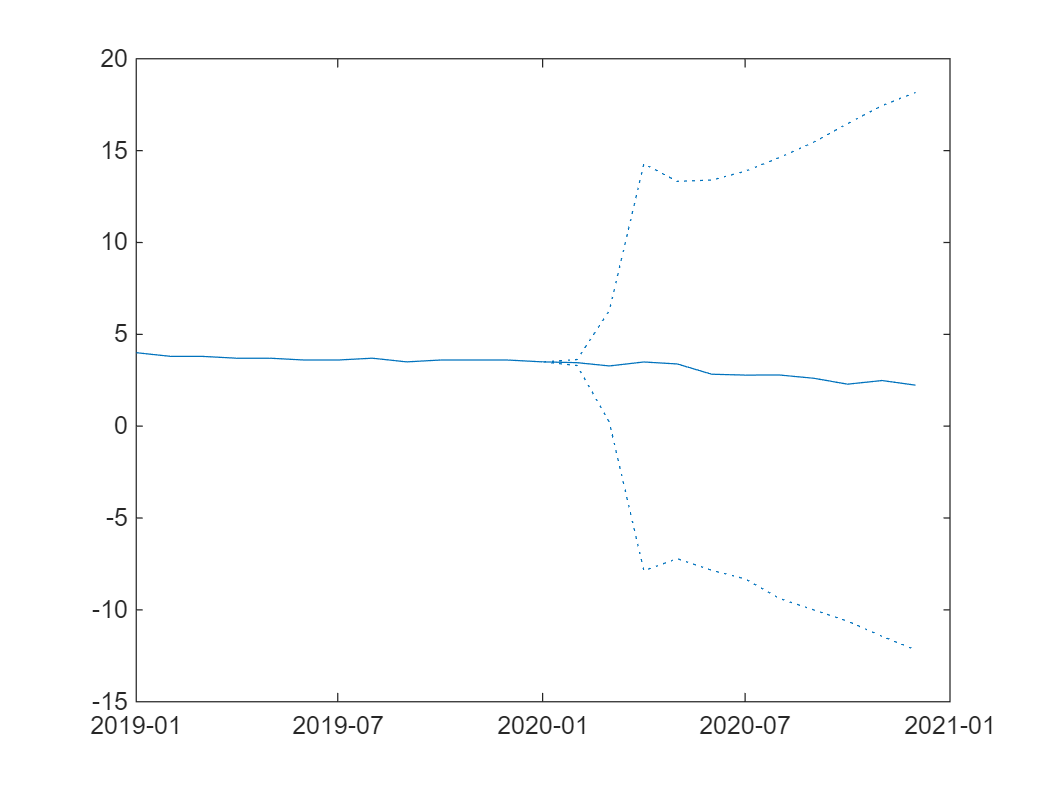

fcastTbx1 = modelS.forecast(fcastSpan1);
fcastTbx1 = tablex.apply(fcastTbx1, prctilesFunc);

tablex.plot( ...
    fcastTbx1, "UNEMP", ...
    plotSettings={"color", defaultColors(1, :), {"lineStyle"}, {":"; "-"; ":"}} ...
);

### Start forecast at the end of the sample

setting up the sample, start forecast

fcastStart2 = datex.shift(modelS.Meta.EstimationEnd, -4);
fcastEnd2 = datex.shift(modelS.Meta.EstimationEnd, +6);
fcastSpan2 = datex.span(fcastStart2, fcastEnd2);


Standard

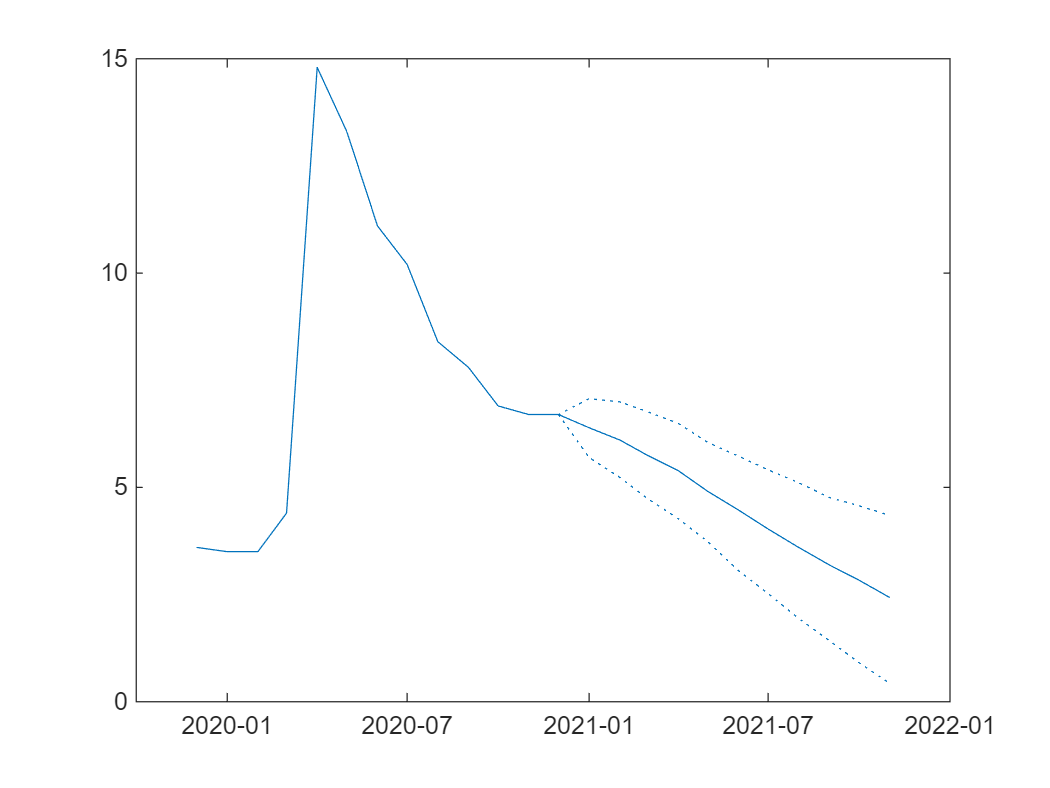

fcastTbx2 = modelS.forecast(fcastSpan2);
fcastTbx2 = tablex.apply(fcastTbx2, prctilesFunc);

tablex.plot( ...
    fcastTbx2, "UNEMP", ...
    plotSettings={"color", defaultColors(1, :), {"lineStyle"}, {":"; "-"; ":"}} ...
);

## Open questions

- As for the Minesotta-prior part, should we use the same std scaling(s) as in BEAR (paper uses AR(1) instead of the lag structure of the model)?

- How to set Sigma for historical, undonditional forecasts? We recommend the current solution, but open for discussion

- How to handle the issue with the neeed of Optim toolbox? 